p1 = rand([3 1])*10;

k1 = rand([3 1]);
k1 = k1/norm(k1);

k2 = rand([3 1]);
k2 = k2/norm(k2);

theta1 = rand()*2*pi-pi

theta1 = 0.2558

theta2 = rand()*2*pi-pi

theta2 = 1.9357


p2 = rot(k2, -theta2)*rot(k1,theta1)*p1;

[t1,t2] = subproblem2(p2,p1,k1,k2)

t1 =    -0.2558
    0.1837


t2 =     1.9357
   -0.0312



[t1,t2] = subproblem2_linear(p1,p2,k1,k2)

t1 =     0.2558   -0.1837


t2 =     1.9357   -0.0312


N_trials = 1000

N_trials = 1000

N_attempts = 100

N_attempts = 100

T_orig = [];
T_linear = [];

for i = 1:N_trials
    p1 = rand([3 1])*10;

    k1 = rand([3 1]);
    k1 = k1/norm(k1);
    
    k2 = rand([3 1]);
    k2 = k2/norm(k2);
    
    theta1 = rand()*2*pi-pi;
    theta2 = rand()*2*pi-pi;
    
    p2 = rot(k2, -theta2)*rot(k1,theta1)*p1;
    
    tic;
    for j = 1:N_attempts
    [t1,t2] = subproblem2(p2,p1,k1,k2);
    end
    t = toc;
    T_orig = [T_orig t/N_attempts];

    tic
    for j = 1:N_attempts
    [t1,t2] = subproblem2_linear(p1,p2,k1,k2);
    end
    t = toc;
    T_linear = [T_linear t/N_attempts];
end
T_linear = rmoutliers(T_linear);
T_orig = rmoutliers(T_orig);
%T_grt_opt = rmoutliers(T_grt_opt);
mean(T_orig)

ans = 1.4334e-05

mean(T_linear)

ans = 8.8300e-06


mean(T_orig)/mean(T_linear)

ans = 1.6233

mean(T_linear)/mean(T_orig)

ans = 0.6160

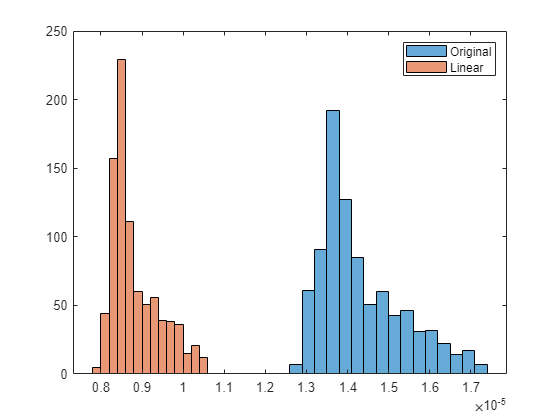


histogram(T_orig); hold on
histogram(T_linear); hold off
legend("Original", "Linear")